clc, clear all, close all;

path = pwd + "/30bpm5c40sps_1-50sw/";
t_fullpath = join([path, "00_mahalanobis.csv"], "");
t_num = readmatrix(t_fullpath);

r_fullpath = join([path, "00_rawvals.csv"], "");
r_num = readmatrix(r_fullpath);

t_time = t_num(:, 3);
t_dist = t_num(:, 2);
t_avg = mean(t_dist);

t_min_y = min(t_dist) - 5;
t_max_y = max(t_dist) + 5;

ids = ["e280116060000205403de047", "e280116060000205403e136b"];
epc = readtable(r_fullpath).epc96(:);

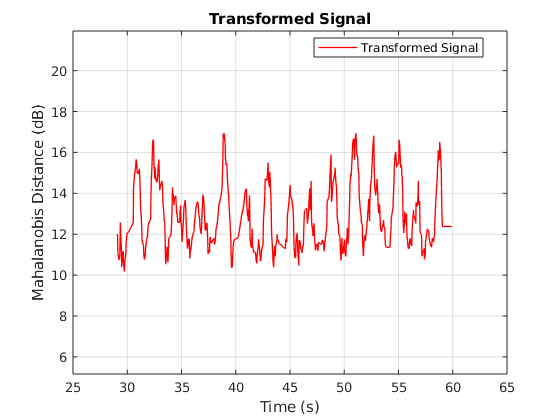


r_time = r_num(:, 3);
r_time = r_time(epc == ids(1));
r_rssi = r_num(:, 2);
r_rssi = r_rssi(epc == ids(1));

figure;
plot(t_time, t_dist, 'red', 'linewidth', 1);
xlabel('Time (s)'), ylabel('Mahalanobis Distance (dB)');
grid on, title('Transformed Signal');
ylim([t_min_y, t_max_y]);
xlim([25,65]);
%yline(t_avg);
legend('Transformed Signal', 'location', 'best');

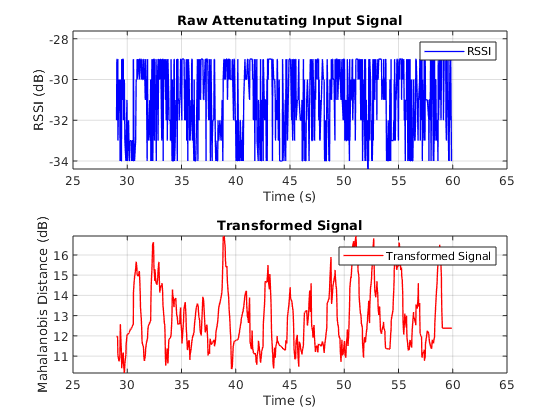


t_range = max(t_dist) - min(t_dist);
r_y_min = mean(r_rssi) - t_range / 2;
r_y_max = mean(r_rssi) + t_range / 2;

figure;
tiledlayout(2, 1);

ax1 = nexttile;
plot(r_time, r_rssi, 'b', 'linewidth', 1);
xlabel('Time (s)'), ylabel('RSSI (dB)');
grid on, title('Raw Attenutating Input Signal');
legend('RSSI', "Location","best");
xlim([25, 65]);
ylim([r_y_min, r_y_max]);

ax2 = nexttile;
plot(ax2, t_time, t_dist, 'red', 'linewidth', 1);
xlabel('Time (s)'), ylabel('Mahalanobis Distance (dB)');
grid on, title('Transformed Signal');
ylim([min(t_dist), max(t_dist)]);
xlim([25,65]);
%yline(t_avg);
legend('Transformed Signal', 'location', 'best');